# Plot the Poynting vector in Fourier space of the SFG scattered field

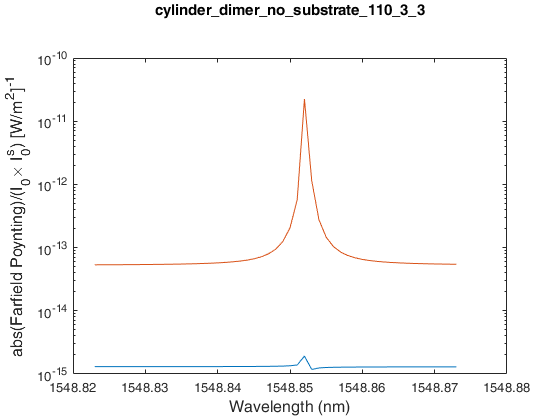

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis'));
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed'));

cylinder_dimer_no_substrate_110_13 = ["cylinder_dimer_no_substrate_110_13_1",...
    "cylinder_dimer_no_substrate_110_13_2","cylinder_dimer_no_substrate_110_13_3",...
    "cylinder_dimer_no_substrate_110_13_4","cylinder_dimer_no_substrate_110_13_5",...
    "cylinder_dimer_no_substrate_110_13_6","cylinder_dimer_no_substrate_110_13_7",...
    "cylinder_dimer_no_substrate_110_13_8","cylinder_dimer_no_substrate_110_13_9",...
    "cylinder_dimer_no_substrate_110_13_11","cylinder_dimer_no_substrate_110_13_12",...
    "cylinder_dimer_no_substrate_110_13_13"];
cylinder_dimer_no_substrate_111_28 = ["cylinder_dimer_no_substrate_111_28_1",...
    "cylinder_dimer_no_substrate_111_28_2","cylinder_dimer_no_substrate_111_28_3",...
    "cylinder_dimer_no_substrate_111_28_4","cylinder_dimer_no_substrate_111_28_5",...
    "cylinder_dimer_no_substrate_111_28_6","cylinder_dimer_no_substrate_111_28_7",...
    "cylinder_dimer_no_substrate_111_28_8","cylinder_dimer_no_substrate_111_28_9",...
    "cylinder_dimer_no_substrate_111_28_11","cylinder_dimer_no_substrate_111_28_12",...
    "cylinder_dimer_no_substrate_111_28_13"];

fig = figure;
                
%for job = ["spheres_3_3"]% "paris_4_4_2"]
%for job = ["paris_2_2" "paris_4_5_2" "paris_4_4_2"]
for job = "cylinder_dimer_no_substrate_110_3_3"
    eval(job);
    load([options.output_dir_final 'derived_values.mat']);
    load([options.output_dir_final 'cut_plane\sum_fft.mat']);
    extra_options = matthew_extra_options(options);
    
    wlengths = 299792458./derived_values.signal.freq;
    denom = derived_values.parameters.I0*derived_values.parameters.I0_i;
    
    for cut_plane_index = 1:length(extra_options.cut_plane)
        for direction = extra_options.direction
            
            [FTx, FTy, FTz,FThx, FThy, FThz, FTpoynting] = ...
                matthew_get_fft_of_cut_plane_all_freqs(sum_fft, ...
                extra_options.cut_plane(cut_plane_index), direction);
            
            for FT_num = 5%1:5
                switch FT_num
                    case 1
                        FTxyz = FTx;
                        FThxyz = FThx;
                    case 2
                        FTxyz = FTy;
                        FThxyz = FThy;
                    case 3
                        FTxyz = FTz;
                        FThxyz = FThz;
                    case 4
                        FTxyz = abs(FTx).^2 + abs(FTy).^2;
                        FThxyz = abs(FThx).^2 + abs(FThy).^2;
                    otherwise
                        FTxyz = FTpoynting;
                end
                    
                [X,Y] = meshgrid(...
                    -2/pi-4/(pi*(length(FTxyz)-1)):4/(pi*(length(FTxyz)-1)):...
                            2/pi-4/(pi*(length(FTxyz)-1)),...
                    -2/pi-4/(pi*(length(FTxyz)-1)):4/(pi*(length(FTxyz)-1)):...
                            2/pi-4/(pi*(length(FTxyz)-1)));
                        
                %fig = figure;
                semilogy(wlengths, (abs(FTxyz(:,2,2))/denom), 'MarkerSize', 12);
                
                hold on;
                
                all_orders = abs(FTxyz(:,1,1)) + abs(FTxyz(:,1,2)) + abs(FTxyz(:,1,3)) + ...
                    abs(FTxyz(:,2,1)) + abs(FTxyz(:,2,2)) + abs(FTxyz(:,2,3)) + ...
                    abs(FTxyz(:,3,1)) + abs(FTxyz(:,3,2)) + abs(FTxyz(:,3,3));
                
                semilogy(wlengths, (abs(all_orders)/denom));
                %plot(log10(abs(FTxyz(:,2,2))));
                %{
                imagesc(abs(FTxyz));
                view(0,-90);
                xlabel('m_x')
                ylabel('m_y')
                xticks([1 2 3]);
                xticklabels({'-1','0','1'});
                yticks([1 2 3]);
                yticklabels({'-1','0','1'});
                cb = colorbar;
                set(gca,'ColorScale','log');
                ylabel(cb, 'P_k (a.u.)');
                switch FT_num
                    case 1
                        title('|FFT(E_x)|');
                    case 2
                        title('|FFT(E_y)|');
                    case 3
                        title('|FFT(E_z)|');
                    case 4
                        title('|FFT(E_x)|^2+|E_y|^2');
                    otherwise
                        title({job, strcat("Theta = ",...
                            sweep_data(sweep_num,:).theta)},...
                            'Interpreter', 'none');
                end
                colormap hot;
                %}
                %axis tight;
                %axis([2035 2065 4e-21 7e-10]);
                ylabel('abs(Farfield Poynting)/(I_0\times I_0^s) [W/m^2]^{-1}', 'FontSize', 12);
                xlabel('Wavelength (nm)', 'FontSize', 12);
                %leg = legend({'Zeroth Order', 'All Orders'});
                title({job, "",""}, 'Interpreter', 'none');
                fig.UserData = "test of UserData property";
                saveas(fig, strcat("C:\Users\Matthew\Downloads\",job, "_fft"), 'png');
            end
        end
    end
end